## PARAMETROS

clc; clear; close all;

% ==============================
% PARÂMETROS
% ==============================

p.m = 0.022;
p.g = 9.81;
p.kfm = 1.8632e-5;
p.Kl = 0.0000415;
p.b = 0.408;

p.x0 = 0.01;
p.i0 = 1.0767;

p.R = 13.5;
p.u0 = p.i0 * p.R;

% Controle
p.Kp = 50;
p.Ki = 0;
p.Kd = 0;

% ==============================
% CONDIÇÕES INICIAIS
% ==============================

y0 = [p.i0; p.x0; 0; 0];

tspan = [0 50];

% ==============================
% SIMULAÇÃO
% ==============================

[t, y] = ode45(@(t,y) odePID(t,y,p), tspan, y0);

## PLOTS

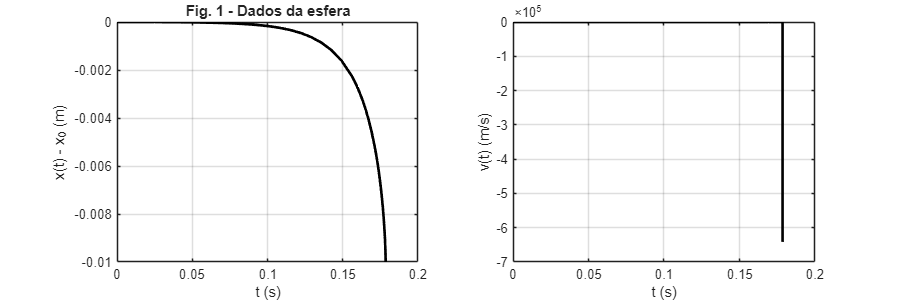

% Estados
i = y(:,1);
x = y(:,2);
v = y(:,3);
E = y(:,4);

% ==============================
% FIGURA 1 - POSIÇÃO E VELOCIDADE
% ==============================

figure('Position',[100 100 900 300])

subplot(1,2,1)
plot(t, x - p.x0, 'k', 'LineWidth', 2)
grid on
xlabel('t (s)')
ylabel('x(t) - x_0 (m)')
title('Fig. 1 - Dados da esfera')

subplot(1,2,2)
plot(t, v, 'k', 'LineWidth', 2)
grid on
xlabel('t (s)')
ylabel('v(t) (m/s)')

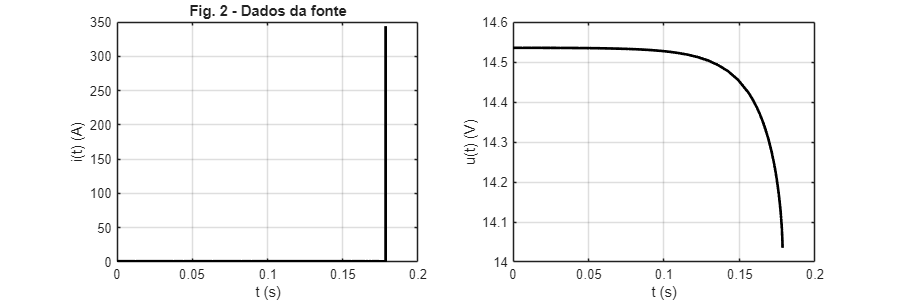


% ==============================
% FIGURA 2 - CORRENTE E CONTROLE
% ==============================

figure('Position',[100 100 900 300])

subplot(1,2,1)
plot(t, i, 'k', 'LineWidth', 2)
grid on
xlabel('t (s)')
ylabel('i(t) (A)')
title('Fig. 2 - Dados da fonte')

% Controle u(t)
u = p.Kp*(x - p.x0) + p.Ki*E + p.Kd*v + p.u0;

subplot(1,2,2)
plot(t, u, 'k', 'LineWidth', 2)
grid on
xlabel('t (s)')
ylabel('u(t) (V)')

## FUNÇÕES

function [fm, Bl, L] = calculoParametros(i, x,p)
    fm = p.kfm *(i^2/x^2);
    Bl = fm/i;
    L = p.Kl/x + p.b;
end

function dy = odePID(t, y, p)

    % Estados
    i = y(1);
    x = y(2);
    v = y(3);
    E = y(4);

    % Parâmetros físicos
    [fm, Bl, L] = calculoParametros(i, x, p);

    % Erro
    e = x - p.x0;

    % Controle
    delta_u = p.Kp*e + p.Kd*v + p.Ki*E;
    u = p.u0 + delta_u;

    % Dinâmica
    di = -(p.R/L)*i - (Bl/L)*v + u/L;
    dx = v;
    dv = p.g - fm/p.m;
    dE = e;

    dy = [di; dx; dv; dE];

end